clockPeriod = 4e-9;
clockHz = 1/clockPeriod;
nPulses = 5;
TTNB = clockPeriod*round(360*1e-6/clockPeriod)

TTNB = 3.6000e-04

TTNBLength = TTNB/clockPeriod;
nTicks = TTNB*nPulses/clockPeriod 

nTicks = 450000

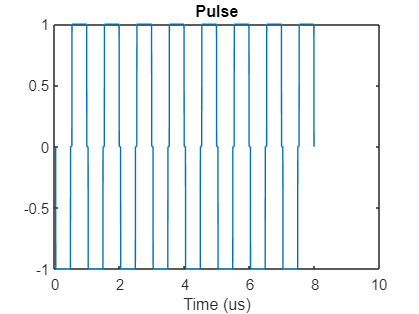

pulse = genWvfm([1,0.9,16,1]);
pLength = length(pulse);
TxTime =  nTicks*clockPeriod;
signal = zeros(nTicks,1);
for i = 1:nPulses
    pStart = 1 + (i-1)*TTNBLength;
    pEnd = pStart + pLength - 1;
    signal(pStart:pEnd) = pulse;
end

time = (1:nTicks)*clockPeriod;
frequency = ((clockHz/nTicks) * ((1:nTicks)-1))*1e-6;

plot(linspace(0,pLength*clockPeriod*1e6,pLength),pulse)
xlabel('Time (us)')
title('Pulse')

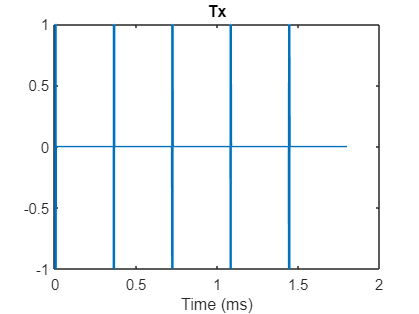


plot(time*1e3,signal)
xlabel('Time (ms)')
title('Tx')

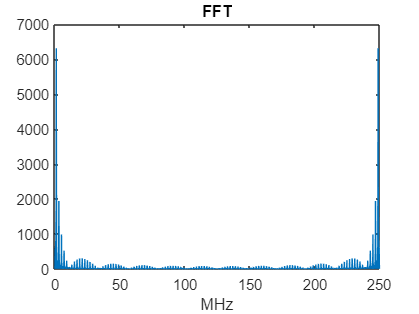


spect = fft(signal);
plot(frequency,abs(spect))
xlabel('MHz')
title('FFT')

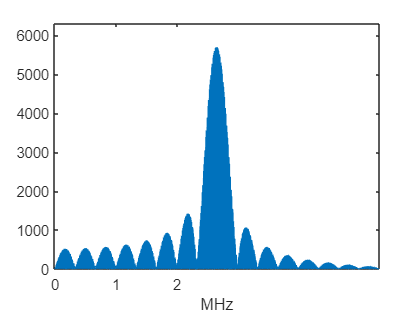


plot(frequency,abs(spect))
xlim([0,2])
xlabel('MHz')


%test = sin(linspace(1,2*pi,1000))+sin(10*linspace(1,2*pi,1000));
%plot(abs(fft(test)))
%xlim([1,20])

PRF = 1/TTNB * 1e-3 %kHz

PRF = 2.7778

% Is PRF always the lowest

dutyCycle = genDC(signal,TxTime*1e6);
disp('Duty Cycle in %:')

Duty Cycle in %:


disp(dutyCycle*100)

    2.0267

